## **Covid Detection Transfer Learning (shufflenet) data augmentation**

## Load Data 

imdsTest = imageDatastore(fullfile('COVID19_CT_seg_20cases', 'test'),'IncludeSubfolders',true,'LabelSource','foldernames');
imdsTrain = imageDatastore(fullfile('UCSD_combined', 'train'),'IncludeSubfolders',true,'LabelSource','foldernames');

## Load Pretrained Network

net = shufflenet;

Use `analyzeNetwork` to display an interactive visualization of the network architecture and detailed information about the network layers.

% analyzeNetwork(net);

net.Layers(1);
inputSize = net.Layers(1).InputSize;

## Replace Final Layers

Extract the layer graph from the trained network. If the network is a `SeriesNetwork` object, such as AlexNet, VGG-16, or VGG-19, then convert the list of layers in `net.Layers` to a layer graph.

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end 

Find the names of the two layers to replace. You can do this manually or you can use the supporting function [findLayersToReplace](matlab:edit(fullfile(matlabroot,'examples','nnet','main','findLayersToReplace.m'))) to find these layers automatically. 

[learnableLayer,classLayer] = findLayersToReplace(lgraph);
[learnableLayer,classLayer];

In most networks, the last layer with learnable weights is a fully connected layer. Replace this fully connected layer with a new fully connected layer with the number of outputs equal to the number of classes in the new data set (5, in this example). In some networks, such as SqueezeNet, the last learnable layer is a 1-by-1 convolutional layer instead. In this case, replace the convolutional layer with a new convolutional layer with the number of filters equal to the number of classes. To learn faster in the new layer than in the transferred layers, increase the learning rate factors of the layer.

numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

The classification layer specifies the output classes of the network. Replace the classification layer with a new one without class labels. `trainNetwork` automatically sets the output classes of the layer at training time. 

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

frozen = 1;
layers(1:frozen) = freezeWeights(layers(1:frozen));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

%***Image augmentation with variability***%
    % Use an augmented image datastore to automatically resize the training images. 
    % Specify additional augmentation operations to perform on the training images: 
    % randomly flip the training images along the vertical axis and randomly translate them 
    % up to 30 pixels and scale them up to 10% horizontally and vertically. 
    % Data augmentation helps prevent the network from overfitting and memorizing 
    % the exact details of the training images.  
    

    pixelRange = [-30 30];
    scaleRange = [0.9 1.1];
    rotRange = [-90 90];
    imageAugmenter = imageDataAugmenter( ...
        'RandXReflection',true, ...
        'RandXTranslation',pixelRange, ...
        'RandYTranslation',pixelRange, ...
        'RandXScale',scaleRange, ...
        'RandYScale',scaleRange, ...
        'RandRotation', rotRange);
    
    augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
        'DataAugmentation',imageAugmenter, 'ColorPreprocessing','gray2rgb');

    
% Augment data to fit new network
% augimdsTrain = augmentedImageDatastore(inputSize,imdsTrain,"ColorPreprocessing","gray2rgb");
augimdsTest = augmentedImageDatastore(inputSize,imdsTest,"ColorPreprocessing","gray2rgb");

Specify the training options.

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',5, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'Verbose',false);

## Train the network using the training data.

all_ACCs = zeros(0);
all_Fscores = zeros(0);
% Initialize true positive, true negative, false positive, false negative.
sum_TP = 0;
sum_TN = 0;
sum_FP = 0;
sum_FN = 0;
for runs = 1:5
    net = trainNetwork(augimdsTrain,lgraph,options);

## Classify Test Images

Classify the test images using the fine-tuned network, and calculate the test accuracy.

    [YPred,probs] = classify(net,augimdsTest);
    
    % Get number of images.
    numImages = size(YPred,1);
    avg_accs = zeros([0,2]);
    % Index tracker.
    total_idx = 1;
    for i = 1:numImages/3
        % Reset sums.
        covidSum = 0;
        noncovidSum = 0;
        % Get the sum of the patient's probability of covid and noncovid
        for j = 1:3
            covidSum = covidSum + probs(total_idx,1);
            noncovidSum = noncovidSum + probs(total_idx,2);
            total_idx = total_idx + 1;
        end
        avg_accs(i,1) = round(covidSum/3,4);
        avg_accs(i,2) = round(noncovidSum/3,4);
    end
    
    for i = 1:numImages/3
        % Print patient info and results
        if(i < 10)
            fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
            fprintf('\t\t\t Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
        else
                    fprintf('Patient %d >> Avg COVID Probability = %.4f\n',i,avg_accs(i,1));
            fprintf('\t\t\t  Avg nonCOVID Probability = %.4f\n',avg_accs(i,2));
        end
    end

Patient 1 >> Avg COVID Probability = 0.9703


			 Avg nonCOVID Probability = 0.0297


Patient 2 >> Avg COVID Probability = 0.9154


			 Avg nonCOVID Probability = 0.0846


Patient 3 >> Avg COVID Probability = 0.7482


			 Avg nonCOVID Probability = 0.2518


Patient 4 >> Avg COVID Probability = 0.5386


			 Avg nonCOVID Probability = 0.4614


Patient 5 >> Avg COVID Probability = 0.1147


			 Avg nonCOVID Probability = 0.8853


Patient 6 >> Avg COVID Probability = 0.5355


			 Avg nonCOVID Probability = 0.4645


Patient 7 >> Avg COVID Probability = 0.8233


			 Avg nonCOVID Probability = 0.1767


Patient 8 >> Avg COVID Probability = 0.6143


			 Avg nonCOVID Probability = 0.3857


Patient 9 >> Avg COVID Probability = 0.9615


			 Avg nonCOVID Probability = 0.0385


Patient 10 >> Avg COVID Probability = 0.0969


			  Avg nonCOVID Probability = 0.9031


Patient 11 >> Avg COVID Probability = 0.8589


			  Avg nonCOVID Probability = 0.1411


Patient 12 >> Avg COVID Probability = 0.6109


			  Avg nonCOVID Probability = 0.3891


Patient 13 >> Avg COVID Probability = 0.4717


			  Avg nonCOVID Probability = 0.5283


Patient 14 >> Avg COVID Probability = 0.7337


			  Avg nonCOVID Probability = 0.2663


Patient 15 >> Avg COVID Probability = 0.4280


			  Avg nonCOVID Probability = 0.5720


Patient 16 >> Avg COVID Probability = 0.5869


			  Avg nonCOVID Probability = 0.4131


Patient 17 >> Avg COVID Probability = 0.5398


			  Avg nonCOVID Probability = 0.4602


Patient 18 >> Avg COVID Probability = 0.5547


			  Avg nonCOVID Probability = 0.4453


Patient 19 >> Avg COVID Probability = 0.9045


			  Avg nonCOVID Probability = 0.0955


Patient 20 >> Avg COVID Probability = 0.6758


			  Avg nonCOVID Probability = 0.3242


Patient 1 >> Avg COVID Probability = 0.9069


			 Avg nonCOVID Probability = 0.0931


Patient 2 >> Avg COVID Probability = 0.7176


			 Avg nonCOVID Probability = 0.2824


Patient 3 >> Avg COVID Probability = 0.3760


			 Avg nonCOVID Probability = 0.6240


Patient 4 >> Avg COVID Probability = 0.2490


			 Avg nonCOVID Probability = 0.7510


Patient 5 >> Avg COVID Probability = 0.3883


			 Avg nonCOVID Probability = 0.6117


Patient 6 >> Avg COVID Probability = 0.0701


			 Avg nonCOVID Probability = 0.9299


Patient 7 >> Avg COVID Probability = 0.5548


			 Avg nonCOVID Probability = 0.4452


Patient 8 >> Avg COVID Probability = 0.4058


			 Avg nonCOVID Probability = 0.5942


Patient 9 >> Avg COVID Probability = 0.0770


			 Avg nonCOVID Probability = 0.9230


Patient 10 >> Avg COVID Probability = 0.2512


			  Avg nonCOVID Probability = 0.7488


Patient 11 >> Avg COVID Probability = 0.5853


			  Avg nonCOVID Probability = 0.4147


Patient 12 >> Avg COVID Probability = 0.7898


			  Avg nonCOVID Probability = 0.2102


Patient 13 >> Avg COVID Probability = 0.3909


			  Avg nonCOVID Probability = 0.6091


Patient 14 >> Avg COVID Probability = 0.1901


			  Avg nonCOVID Probability = 0.8099


Patient 15 >> Avg COVID Probability = 0.6329


			  Avg nonCOVID Probability = 0.3671


Patient 16 >> Avg COVID Probability = 0.3903


			  Avg nonCOVID Probability = 0.6097


Patient 17 >> Avg COVID Probability = 0.4755


			  Avg nonCOVID Probability = 0.5245


Patient 18 >> Avg COVID Probability = 0.6183


			  Avg nonCOVID Probability = 0.3817


Patient 19 >> Avg COVID Probability = 0.1231


			  Avg nonCOVID Probability = 0.8769


Patient 20 >> Avg COVID Probability = 0.7241


			  Avg nonCOVID Probability = 0.2759


Patient 1 >> Avg COVID Probability = 0.9931


			 Avg nonCOVID Probability = 0.0069


Patient 2 >> Avg COVID Probability = 0.9765


			 Avg nonCOVID Probability = 0.0235


Patient 3 >> Avg COVID Probability = 0.3011


			 Avg nonCOVID Probability = 0.6989


Patient 4 >> Avg COVID Probability = 0.1548


			 Avg nonCOVID Probability = 0.8452


Patient 5 >> Avg COVID Probability = 0.1488


			 Avg nonCOVID Probability = 0.8512


Patient 6 >> Avg COVID Probability = 0.4328


			 Avg nonCOVID Probability = 0.5672


Patient 7 >> Avg COVID Probability = 0.8433


			 Avg nonCOVID Probability = 0.1567


Patient 8 >> Avg COVID Probability = 0.5273


			 Avg nonCOVID Probability = 0.4727


Patient 9 >> Avg COVID Probability = 0.8458


			 Avg nonCOVID Probability = 0.1542


Patient 10 >> Avg COVID Probability = 0.6152


			  Avg nonCOVID Probability = 0.3848


Patient 11 >> Avg COVID Probability = 0.7038


			  Avg nonCOVID Probability = 0.2962


Patient 12 >> Avg COVID Probability = 0.5286


			  Avg nonCOVID Probability = 0.4714


Patient 13 >> Avg COVID Probability = 0.0475


			  Avg nonCOVID Probability = 0.9525


Patient 14 >> Avg COVID Probability = 0.1293


			  Avg nonCOVID Probability = 0.8707


Patient 15 >> Avg COVID Probability = 0.2324


			  Avg nonCOVID Probability = 0.7676


Patient 16 >> Avg COVID Probability = 0.4854


			  Avg nonCOVID Probability = 0.5146


Patient 17 >> Avg COVID Probability = 0.0870


			  Avg nonCOVID Probability = 0.9130


Patient 18 >> Avg COVID Probability = 0.3409


			  Avg nonCOVID Probability = 0.6591


Patient 19 >> Avg COVID Probability = 0.4001


			  Avg nonCOVID Probability = 0.5999


Patient 20 >> Avg COVID Probability = 0.2842


			  Avg nonCOVID Probability = 0.7158


Patient 1 >> Avg COVID Probability = 0.9077


			 Avg nonCOVID Probability = 0.0923


Patient 2 >> Avg COVID Probability = 0.8267


			 Avg nonCOVID Probability = 0.1733


Patient 3 >> Avg COVID Probability = 0.6457


			 Avg nonCOVID Probability = 0.3543


Patient 4 >> Avg COVID Probability = 0.6340


			 Avg nonCOVID Probability = 0.3660


Patient 5 >> Avg COVID Probability = 0.1480


			 Avg nonCOVID Probability = 0.8520


Patient 6 >> Avg COVID Probability = 0.2086


			 Avg nonCOVID Probability = 0.7914


Patient 7 >> Avg COVID Probability = 0.7152


			 Avg nonCOVID Probability = 0.2848


Patient 8 >> Avg COVID Probability = 0.8501


			 Avg nonCOVID Probability = 0.1499


Patient 9 >> Avg COVID Probability = 0.4723


			 Avg nonCOVID Probability = 0.5277


Patient 10 >> Avg COVID Probability = 0.4737


			  Avg nonCOVID Probability = 0.5263


Patient 11 >> Avg COVID Probability = 0.7220


			  Avg nonCOVID Probability = 0.2780


Patient 12 >> Avg COVID Probability = 0.4870


			  Avg nonCOVID Probability = 0.5130


Patient 13 >> Avg COVID Probability = 0.2646


			  Avg nonCOVID Probability = 0.7354


Patient 14 >> Avg COVID Probability = 0.2250


			  Avg nonCOVID Probability = 0.7750


Patient 15 >> Avg COVID Probability = 0.3339


			  Avg nonCOVID Probability = 0.6661


Patient 16 >> Avg COVID Probability = 0.4693


			  Avg nonCOVID Probability = 0.5307


Patient 17 >> Avg COVID Probability = 0.2926


			  Avg nonCOVID Probability = 0.7074


Patient 18 >> Avg COVID Probability = 0.4916


			  Avg nonCOVID Probability = 0.5084


Patient 19 >> Avg COVID Probability = 0.2433


			  Avg nonCOVID Probability = 0.7567


Patient 20 >> Avg COVID Probability = 0.5165


			  Avg nonCOVID Probability = 0.4835


Patient 1 >> Avg COVID Probability = 0.9740


			 Avg nonCOVID Probability = 0.0260


Patient 2 >> Avg COVID Probability = 0.9400


			 Avg nonCOVID Probability = 0.0600


Patient 3 >> Avg COVID Probability = 0.3386


			 Avg nonCOVID Probability = 0.6614


Patient 4 >> Avg COVID Probability = 0.2961


			 Avg nonCOVID Probability = 0.7039


Patient 5 >> Avg COVID Probability = 0.0979


			 Avg nonCOVID Probability = 0.9021


Patient 6 >> Avg COVID Probability = 0.5776


			 Avg nonCOVID Probability = 0.4224


Patient 7 >> Avg COVID Probability = 0.7471


			 Avg nonCOVID Probability = 0.2529


Patient 8 >> Avg COVID Probability = 0.7196


			 Avg nonCOVID Probability = 0.2804


Patient 9 >> Avg COVID Probability = 0.8980


			 Avg nonCOVID Probability = 0.1020


Patient 10 >> Avg COVID Probability = 0.7910


			  Avg nonCOVID Probability = 0.2090


Patient 11 >> Avg COVID Probability = 0.6204


			  Avg nonCOVID Probability = 0.3796


Patient 12 >> Avg COVID Probability = 0.4464


			  Avg nonCOVID Probability = 0.5536


Patient 13 >> Avg COVID Probability = 0.1157


			  Avg nonCOVID Probability = 0.8843


Patient 14 >> Avg COVID Probability = 0.1452


			  Avg nonCOVID Probability = 0.8548


Patient 15 >> Avg COVID Probability = 0.5477


			  Avg nonCOVID Probability = 0.4523


Patient 16 >> Avg COVID Probability = 0.5236


			  Avg nonCOVID Probability = 0.4764


Patient 17 >> Avg COVID Probability = 0.3423


			  Avg nonCOVID Probability = 0.6577


Patient 18 >> Avg COVID Probability = 0.1344


			  Avg nonCOVID Probability = 0.8656


Patient 19 >> Avg COVID Probability = 0.2086


			  Avg nonCOVID Probability = 0.7914


Patient 20 >> Avg COVID Probability = 0.5183


			  Avg nonCOVID Probability = 0.4817


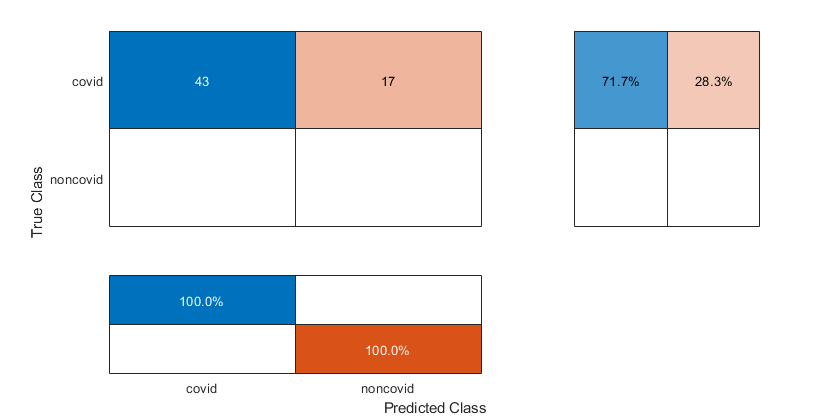

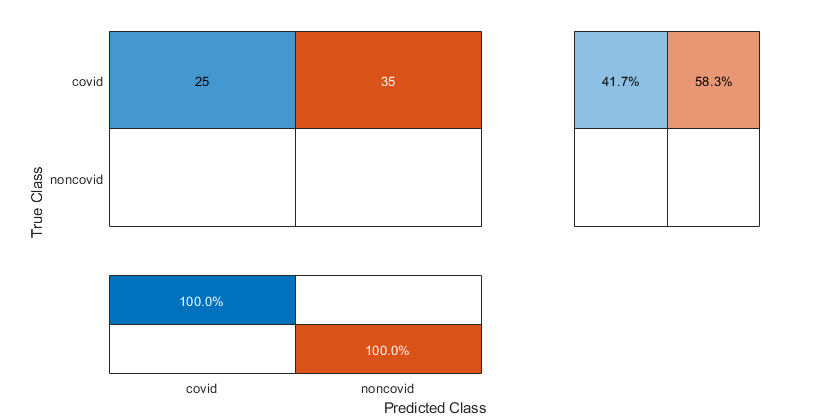

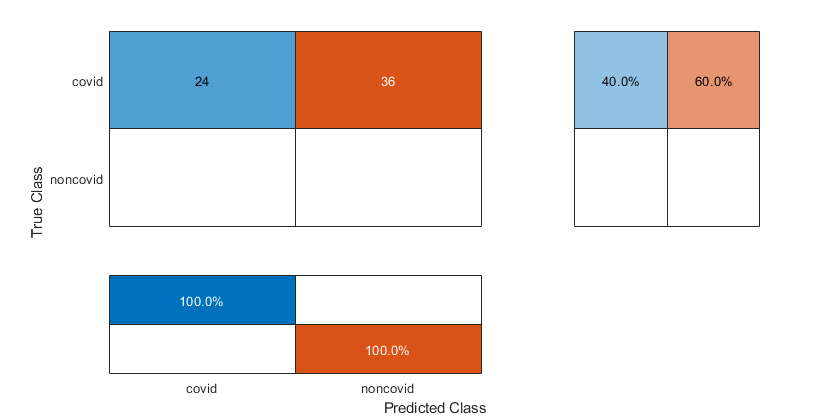

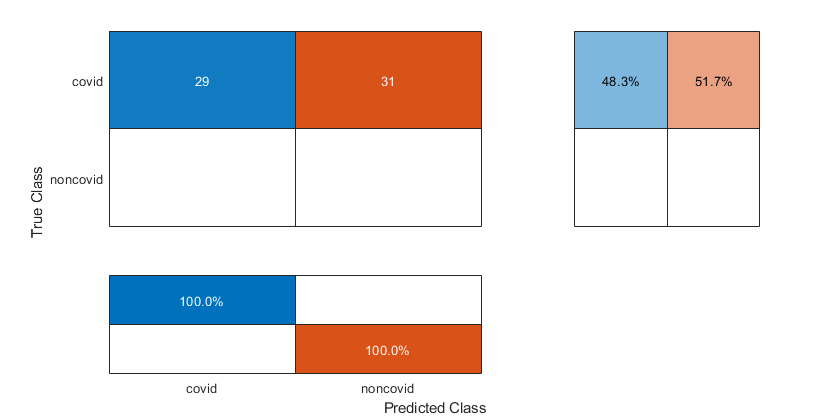

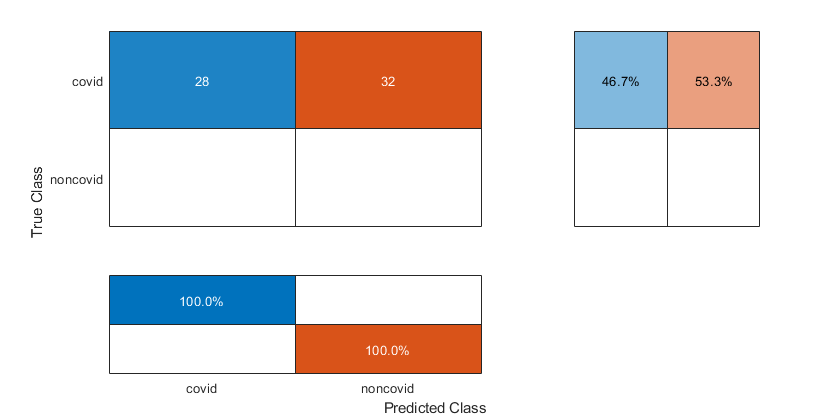

    
    % Extract the class labels from the test data.
    YTest = imdsTest.Labels;
    
    accuracy = mean(YPred == YTest);
    
    % Calculate Average F-score.
    s = max(size(unique(YTest)));
    conf_values = confusionmat(YTest, YPred);
    tp_m = diag(conf_values); 
    for i = 1:s
       % Get true positive, false negative, false positive
        sum_TP = sum_TP + conf_values(1,1);
        TP = conf_values(1,1);
        sum_FN = sum_FN + conf_values(1,2);
        FN = conf_values(1,2);
        sum_FP = sum_FP + conf_values(2,1);
        FP = conf_values(2,1);
        sum_TN = sum_TN + conf_values(2,2);
        TN = conf_values(2,2);
        
        % Calculate Recall, precision, fscore
        Recall = TP /(TP + FN);
        if isnan(Recall)
            Recall = 0;
        end
        % Calculate Precision
        Precision = TP / (TP + FP);
        if isnan(Precision)
            Precision = 0;
        end
        % Calculate FScore
        FScore = (2*(Precision * Recall)) / (Precision+Recall);
        if isnan(FScore)
            FScore = 0;
        end
    end
    
    % Display confusion chart.
    fig = figure;
    conf = confusionchart(YTest, YPred,'RowSummary','row-normalized','ColumnSummary','column-normalized');

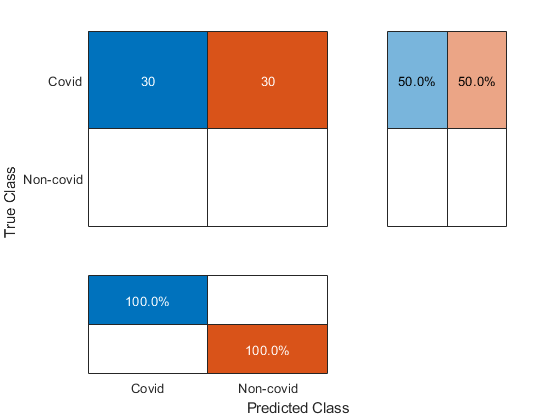

avg_ACC = 0.4967

avg_FScore = 0.6565

stdDev_ACC = 0.1277

stdDev_Fscore = 0.1051

    fig_Position = fig.Position;
    fig_Position(3) = fig_Position(3)*1.5;
    fig.Position = fig_Position;
    
    all_ACCs = [all_ACCs accuracy];
    all_Fscores = [all_Fscores FScore];

end

% Get the average of all of the labels.
sum_TP = round(sum_TP/5);
sum_TN = round(sum_TN/5);
sum_FP = round(sum_FP/5);
sum_FN = round(sum_FN/5);
% Combined CM
combined_mat = [sum_TP,  sum_FN; sum_FP, sum_TN];

% Display combined confusion chart.
figure;
conf = confusionchart(combined_mat,["Covid", "Non-covid"],'RowSummary','row-normalized','ColumnSummary','column-normalized');

avg_ACC = mean(all_ACCs)
avg_FScore = mean(all_Fscores)

stdDev_ACC = std(all_ACCs)
stdDev_Fscore = std(all_Fscores)


Display four sample validation images with predicted labels and the predicted probabilities of the images having those labels. With Actiavation Heatmaps

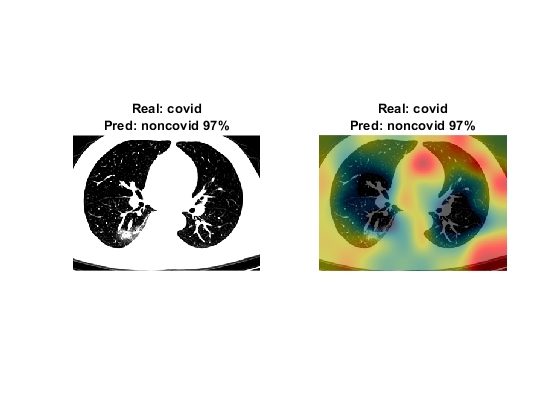

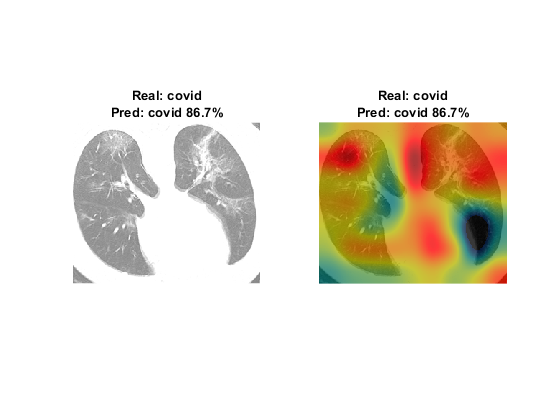

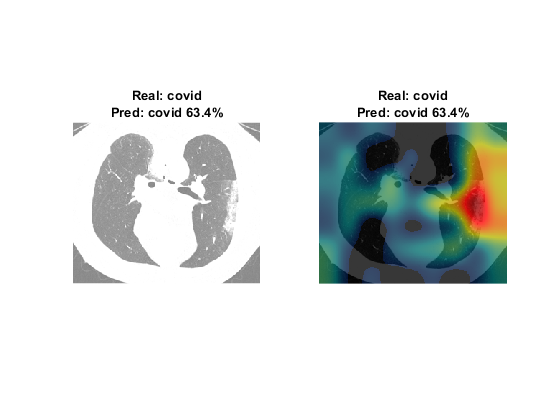

idx = randperm(numel(imdsTest.Files),3);
figure
for i = 1:3 
    I = readimage(imdsTest,idx(i));
    actlabel = YTest(idx(i));
    predlabel = YPred(idx(i));
    
    layerName = 'node_199';
    
    %Compute the activations of the resized image
    % in the ReLU layer that follows the last convolutional layer of the network
    imResized = imresize(I,[inputSize(1), NaN]);
    imageActivations = activations(net,imResized,layerName);
    
    %global average pooling (get average of activations)
    scores = squeeze(mean(imageActivations,[1 2]));
    fcWeights = net.Layers(end-2).Weights;
    fcBias = net.Layers(end-2).Bias;
    
    %get predicted class/classes with highes scores for CAM
    scores =  fcWeights*scores + fcBias;
    [~,classIds] = maxk(scores,2);
    weightVector = shiftdim(fcWeights(classIds(1),:),-1);
    classActivationMap = sum(imageActivations.*weightVector,3);
    
    %get the top class labels and the final normalized class scores
    scores = exp(scores)/sum(exp(scores));     
    maxScores = scores(classIds);
    labels = class(classIds);
    
    %Plot the class activation map
    figure;
    subplot(1,2,1)
    imshow(imResized)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});
    
    subplot(1,2,2)
    CAMshow(imResized,classActivationMap)
    title({"Real: " + string(actlabel), "Pred: " + string(predlabel) + " " + ...
    num2str(100*max(probs(idx(i),:)),3) + "%"});

end


drawnow




HELPER FUNCTIONS FOR CAM

function CAMshow(im,CAM)
    imSize = size(im);
    CAM = imresize(CAM,imSize(1:2));
    CAM = normalizeImage(CAM);
    CAM(CAM<0.2) = 0;
    cmap = jet(255).*linspace(0,1,255)';
    CAM = ind2rgb(uint8(CAM*255),cmap)*255;
    
    combinedImage = double(rgb2gray(im))/2 + CAM;
    combinedImage = normalizeImage(combinedImage)*255;
    imshow(uint8(combinedImage));
end


function N = normalizeImage(I)
    minimum = min(I(:));
    maximum = max(I(:));
    N = (I-minimum)/(maximum-minimum);
end

